# Template of Manipulator Short project: Skull tumor surgery

Authors: 

Team:  

Shared Link with the teacher: 

I spect: 1) Pdf file, 2) Videos demostrating your successful task and your mlx file.

Notes. For better undestanding you can split the videos in the meaninful task.

Remember use the options of serial/link plot: 

'workspace' for centering in the surgery task

'zoom' ...  nice puma ratio aspect

'trail'  .. to see the trajectory

etc..

See all at:

>> help SerialLink/plot

## The Robotic environment (10%)

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

Use: 'c = uisetcolor' to chose your prefered colors

### Operating table.

 It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Define: Vertices and Faces and use  'patch'  functions to model it. See help patch to find and example.

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

**Expected results**

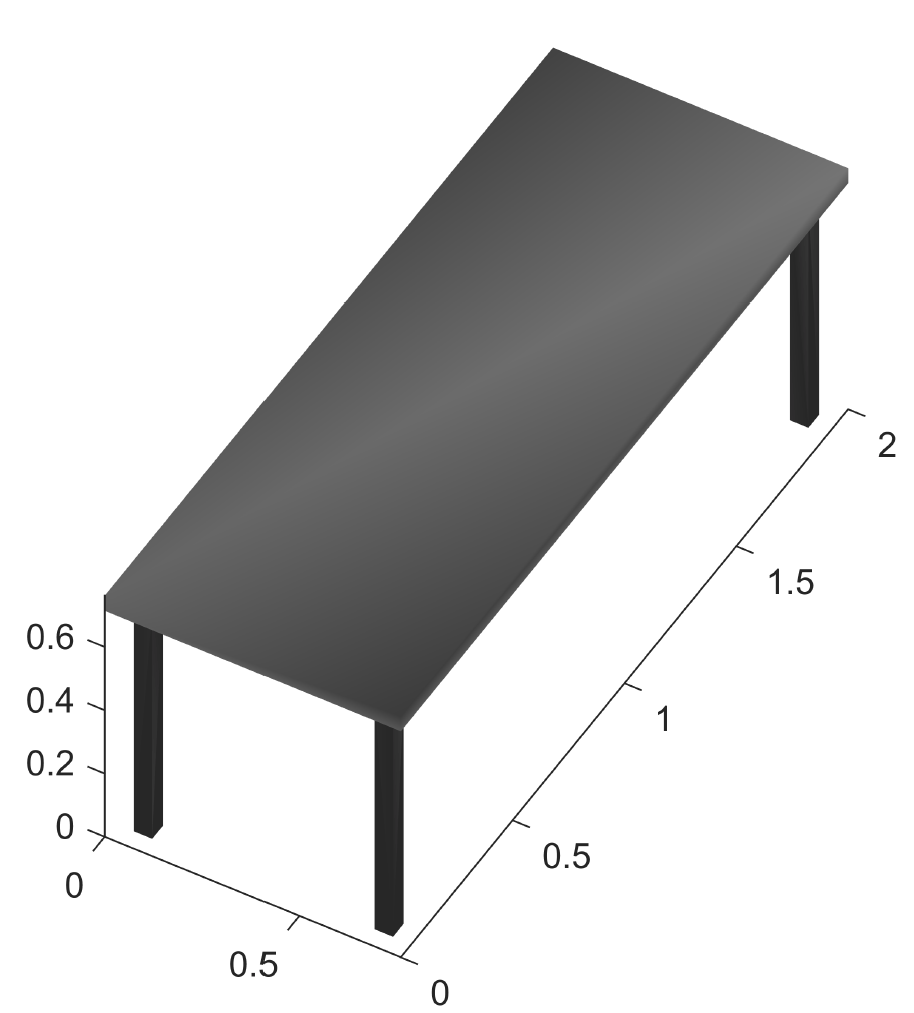

clf
minXMesa = 0

minXMesa = 0

minYMesa = 0

minYMesa = 0

maxXMesa = 2

maxXMesa = 2

maxYMesa = 0.75

maxYMesa = 0.7500

minZMesa = 0.5

minZMesa = 0.5000

maxZMesa = 0.6

maxZMesa = 0.6000

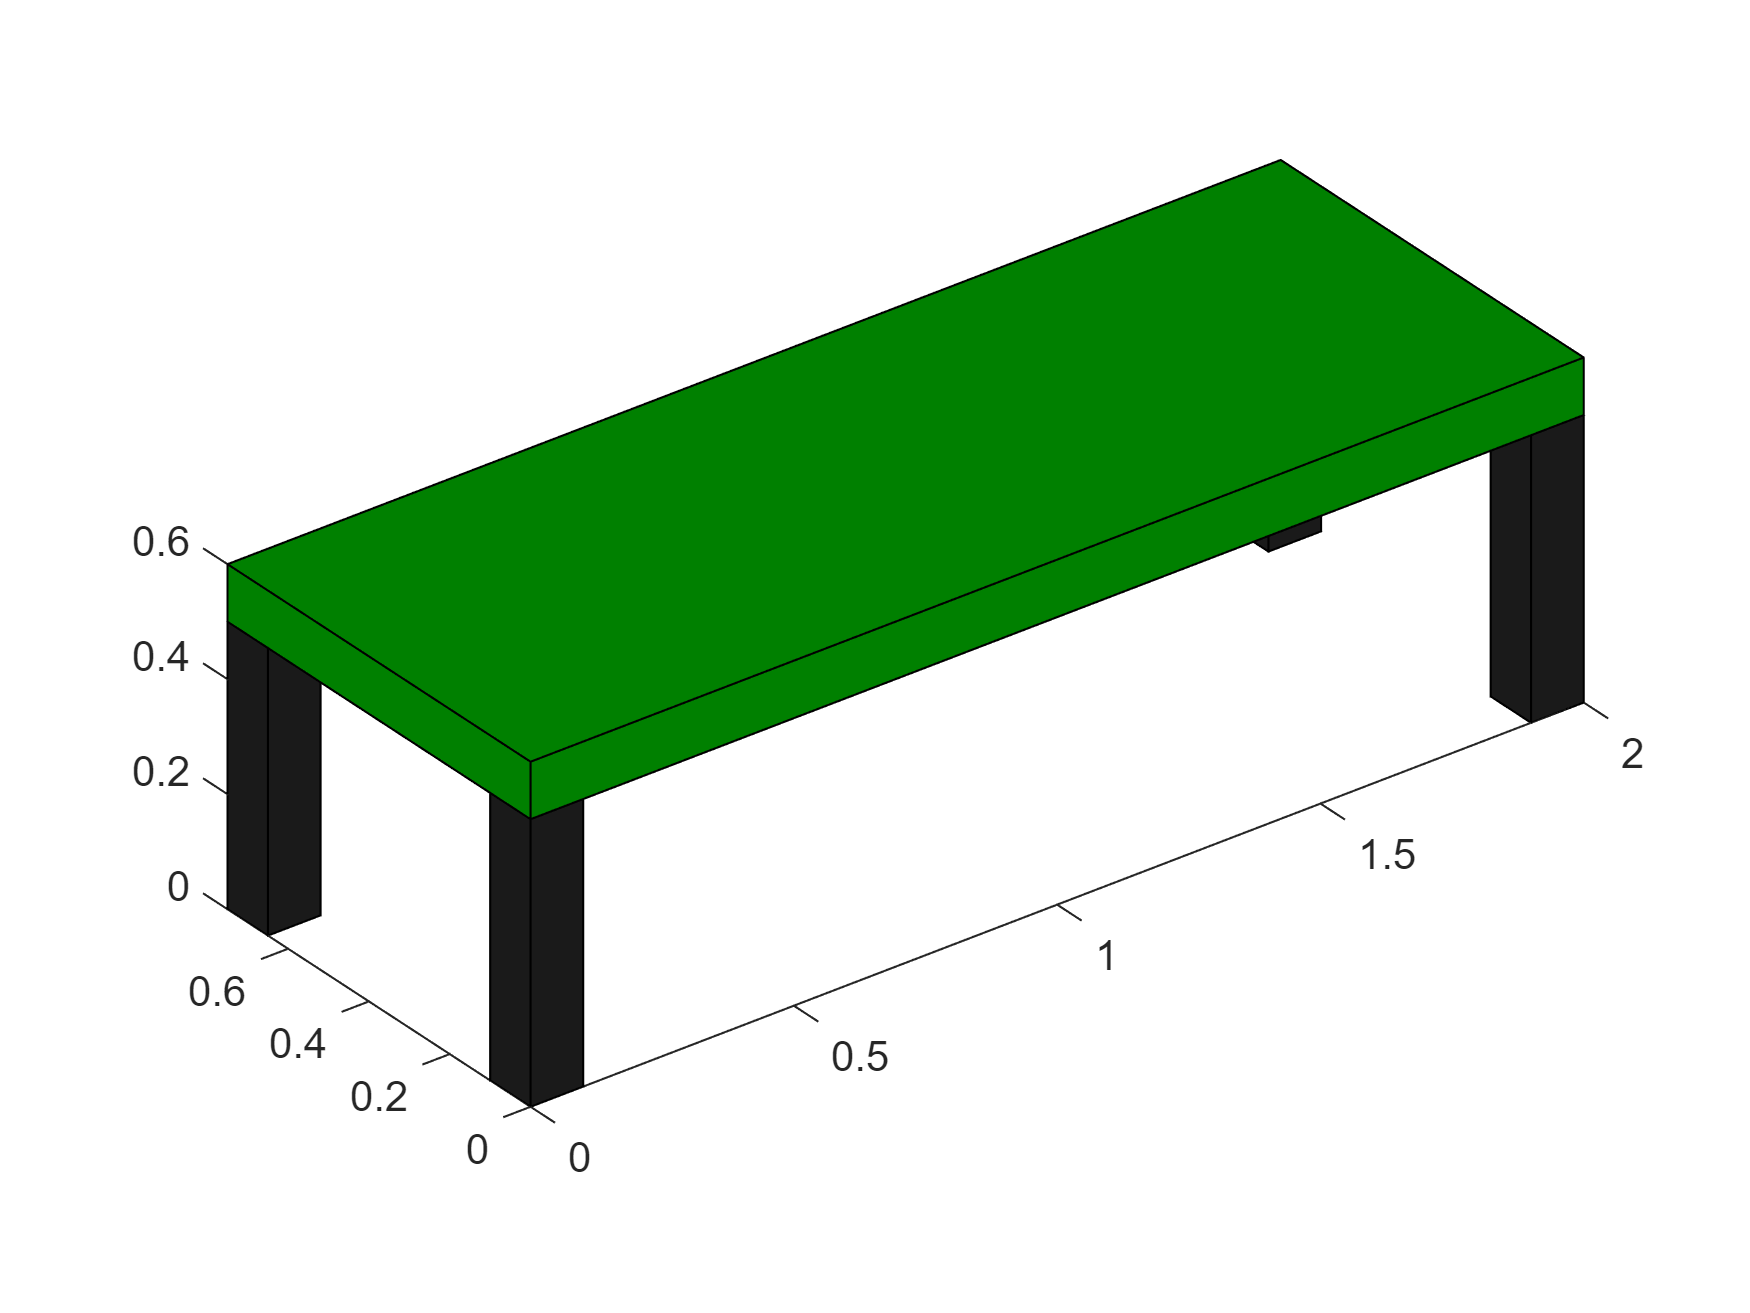

vM = [minXMesa minYMesa minZMesa; minXMesa maxYMesa minZMesa; maxXMesa maxYMesa minZMesa; maxXMesa minYMesa minZMesa;minXMesa minYMesa maxZMesa; minXMesa maxYMesa maxZMesa; maxXMesa maxYMesa maxZMesa; maxXMesa minYMesa maxZMesa];
fM = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];
view(3)

T_M_0 = transl(0)*trotx(0)*troty(0)*trotz(0);

vM2 = vM';
vM2(4,:) = 1;
vM2 = T_M_0 * vM2;
vM2 = vM2(1:3,:)';

patch('Faces',fM,'Vertices',vM2,'FaceColor',[0 0.5 0])


vP1 = vM - [0 0 0.5];
vP1 = vP1 .* [0.05 0.1333 5];
patch('Faces',fM,'Vertices',vP1,'FaceColor',[0.1 0.1 0.1])

vP1 = vM - [0 0 0.5];
vP1 = vP1 .* [0.05 0.1333 5];
patch('Faces',fM,'Vertices',vP1,'FaceColor',[0.1 0.1 0.1])

vP1 = vM - [0 0 0.5];
vP1 = vP1 .* [0.05 0.1333 5];
vP1 = vP1 + [1.9 0 0];
patch('Faces',fM,'Vertices',vP1,'FaceColor',[0.1 0.1 0.1])

vP1 = vM - [0 0 0.5];
vP1 = vP1 .* [0.05 0.1333 5];
vP1 = vP1 + [0 0.65 0];
patch('Faces',fM,'Vertices',vP1,'FaceColor',[0.1 0.1 0.1])

vP1 = vM - [0 0 0.5];
vP1 = vP1 .* [0.05 0.1333 5];
vP1 = vP1 + [1.9 0.65 0];
patch('Faces',fM,'Vertices',vP1,'FaceColor',[0.1 0.1 0.1])

% r = 0.02;
% [XM,YM,ZM] = cylinder(r);
% h = 0.6;
% ZM = ZM*h-0.01;
% 
% hold on
% % surf(XM+0.1,YM+0.1,ZM)
% % surf(XM+0.1,YM+0.65,ZM)
% % surf(XM+1.9,YM+0.1,ZM)
% % surf(XM+1.9,YM+0.65,ZM)
axis equal

### 3D model of a human body 

Situate the human model on the operating table. 

**Expected results**

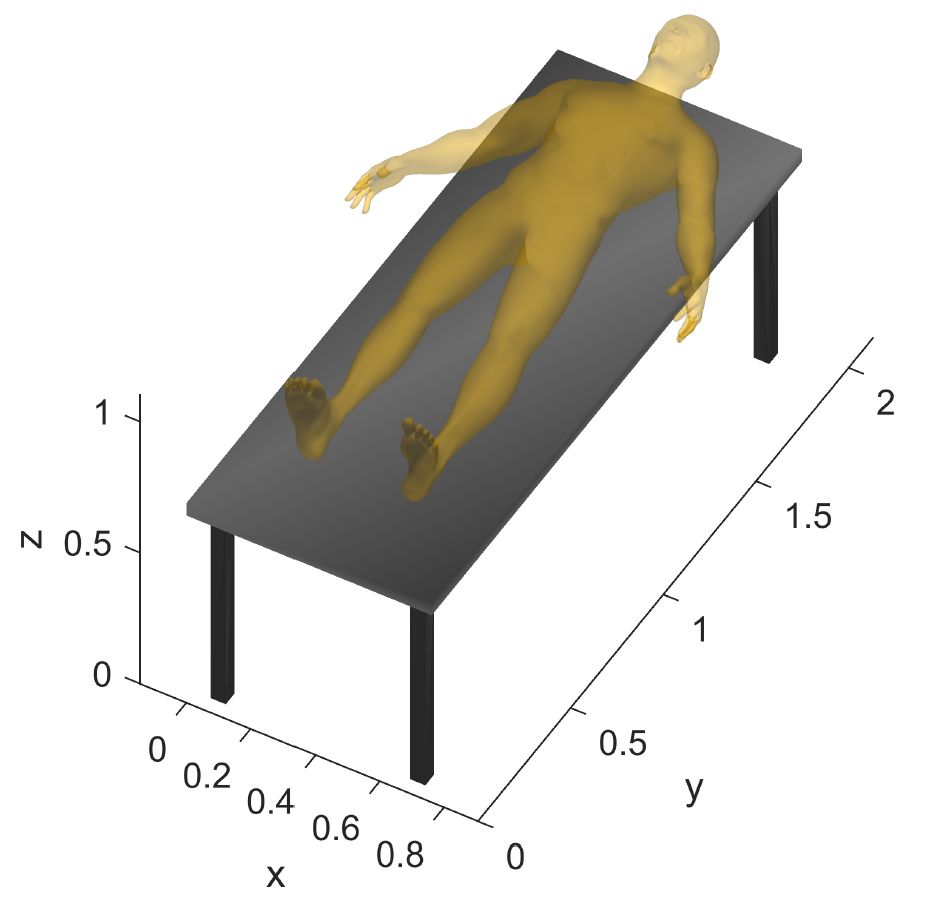

load('F_V_HumanBody.mat')
view(3)
Vh(:,4) = 1;
T_C_M = transl(0.45,0.375,0.77)*trotz(-pi/2)*trotx(-pi/2) * T_M_0;
Vh = T_C_M * Vh'

Vh =     1.7610    1.7649    1.7738    1.7706    1.7789    1.7786    1.7805    1.7844    1.7881    1.7919    1.7961    1.8000    1.7864    1.7948    1.7972    1.8035    1.8068    1.8125    1.8165    1.8214    1.8262    1.8301    1.8359    1.8312    1.8206    1.8419    1.8245    1.8316    1.8383    1.8167    1.8452    1.8084    1.8042    1.8121    1.8100    1.7996    1.7909    1.7894    1.8019    1.7879    1.7792    1.7787    1.7799    1.8131    1.8159    1.8039    1.7922    1.7693    1.7580    1.7589
    0.4893    0.5018    0.4941    0.4857    0.4896    0.4833    0.4987    0.4912    0.5016    0.4930    0.5037    0.4948    0.4831    0.4840    0.4743    0.4853    0.4753    0.4869    0.4768    0.4889    0.4789    0.4912    0.4814    0.4684    0.4663    0.4710    0.5003    0.5027    0.4941    0.4983    0.4846    0.4965    0.5054    0.5068    0.4649    0.4640    0.4530    0.4637    0.4532    0.4739    0.4641    0.4743    0.4533    0.4541    0.4432    0.4425    0.4422    0.4759    0.4667    

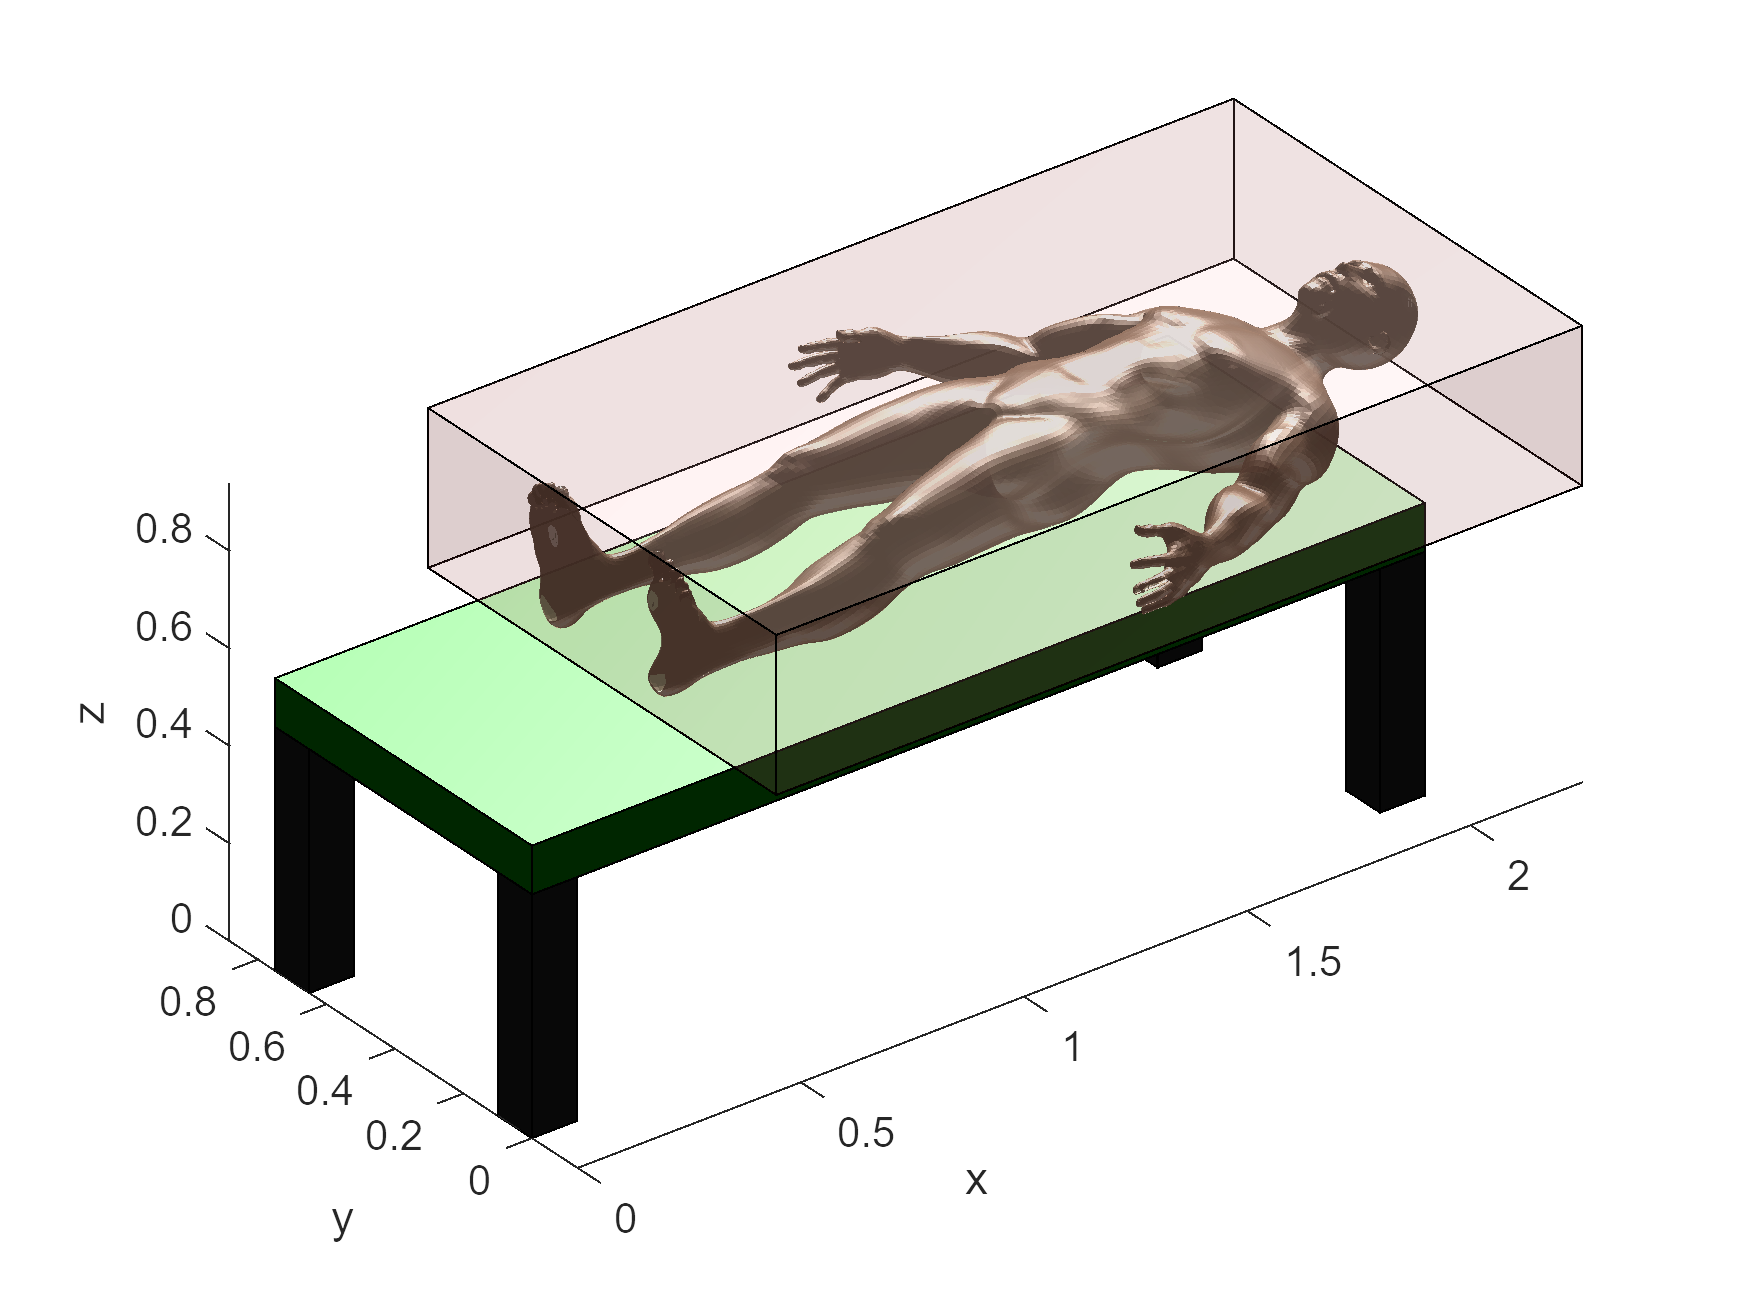

patch('Vertices',Vh(1:3,:)','Faces',Fh,'FaceColor', [0.82 0.64 0.52], 'EdgeColor' , 'none', 'FaceAlpha', 0.8)
axis equal
light('Position',[3,3,3]);
view(3)
%CAJA CONTENEDORA 
minCuerpo = min(Vh');
maxCuerpo = max(Vh');
vCH = [minCuerpo(1) minCuerpo(2) minCuerpo(3); minCuerpo(1) maxCuerpo(2) minCuerpo(3); maxCuerpo(1) maxCuerpo(2) minCuerpo(3); maxCuerpo(1) minCuerpo(2) minCuerpo(3);minCuerpo(1) minCuerpo(2) maxCuerpo(3); minCuerpo(1) maxCuerpo(2) maxCuerpo(3); maxCuerpo(1) maxCuerpo(2) maxCuerpo(3); maxCuerpo(1) minCuerpo(2) maxCuerpo(3)];
fCH = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];
view(3)

xyzlabel
  patch('Faces',fCH,'Vertices',vCH,'FaceColor',[1 0 0],'FaceAlpha',0.1)

### Fiducials

The Radiology Department before to take a Computer Tomography (CT) of the brain, fix three fiducials in the head of the patient for registering purpose,  visit: [https://en.wikipedia.org/wiki/Fiducial](https://en.wikipedia.org/wiki/Fiducial)

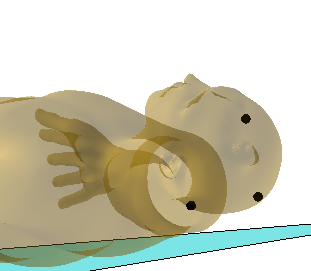

### Dicom image vs Image Reference frame {I}

Get familiar with Dicom Images, Visit: https://www.imaios.com/en/Imaios-Dicom-Viewer#!

Use a container Box of the skull  to infer the Image Reference Frame {I}

See:  6_Plot_Box_Cone.mlx and 7_Help_Image_RF_Containig_Box.fig to inspire yourselt 

**Expected results**

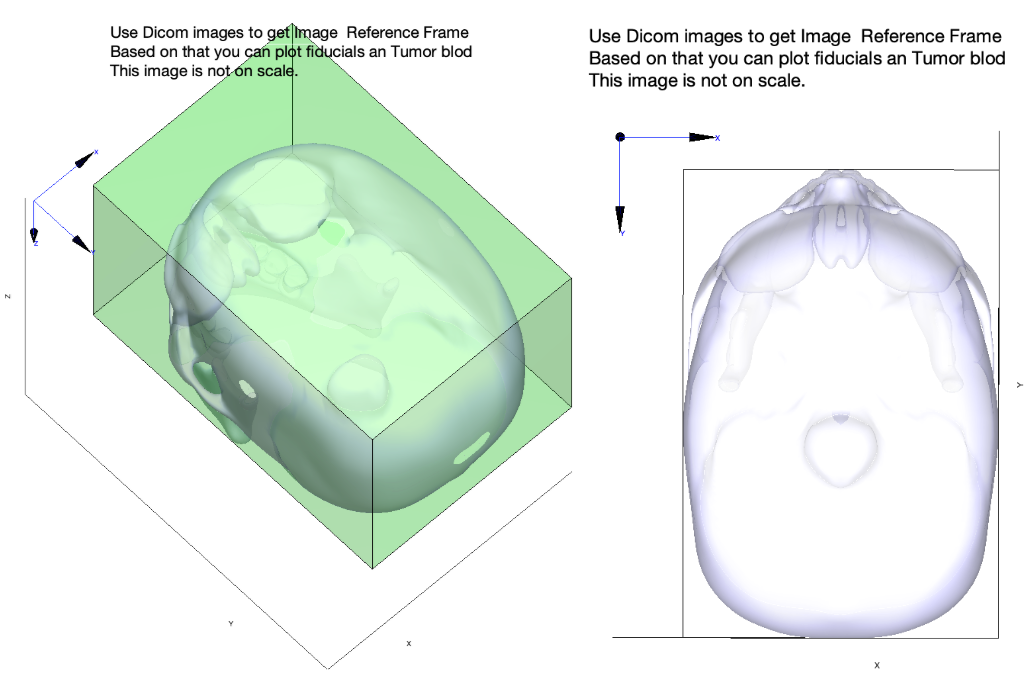

## put your code Here

clf
load('F_V_Skull.mat')
view(3)
Vs(:,4) = 1;
Vs = trotz(pi) * Vs';
Vs = Vs(1:3,:)'

Vs =     0.0127    0.1141    0.0085
    0.0097    0.1154    0.0082
    0.0094    0.1149    0.0110
    0.0124    0.1136    0.0112
    0.0065    0.1165    0.0080
    0.0063    0.1159    0.0108
    0.0061    0.1152    0.0140
    0.0092    0.1142    0.0142
    0.0122    0.1130    0.0143
    0.0033    0.1172    0.0078


light('Position',[1 1 1]);
patch('Vertices',Vs,'Faces',Fs,'FaceColor', [0.5 0.5 0.5], 'EdgeColor' , 'none','FaceAlpha', 0.5)

%CAJA CONTENEDORA
minSkull = (min(Vs))

minSkull =    -0.0765   -0.1077    0.0004


maxSkull = (max(Vs))

maxSkull =     0.0765    0.1194    0.2127


minSkullX = minSkull(1)

minSkullX = -0.0765

minSkullY = minSkull(2)

minSkullY = -0.1077

minSkullZ = minSkull(3)

minSkullZ = 3.8712e-04


maxSkullX = maxSkull(1)

maxSkullX = 0.0765

maxSkullY = maxSkull(2)

maxSkullY = 0.1194

maxSkullZ = maxSkull(3)

maxSkullZ = 0.2127


v= [minSkullX minSkullY minSkullZ;maxSkullX minSkullY minSkullZ;maxSkullX maxSkullY minSkullZ;minSkullX maxSkullY minSkullZ;minSkullX minSkullY maxSkullZ;maxSkullX minSkullY maxSkullZ;maxSkullX maxSkullY maxSkullZ;minSkullX maxSkullY maxSkullZ]

v =    -0.0765   -0.1077    0.0004
    0.0765   -0.1077    0.0004
    0.0765    0.1194    0.0004
   -0.0765    0.1194    0.0004
   -0.0765   -0.1077    0.2127
    0.0765   -0.1077    0.2127
    0.0765    0.1194    0.2127
   -0.0765    0.1194    0.2127


f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8]

f =      1     2     6     5
     2     3     7     6
     3     4     8     7
     4     1     5     8
     1     2     3     4
     5     6     7     8


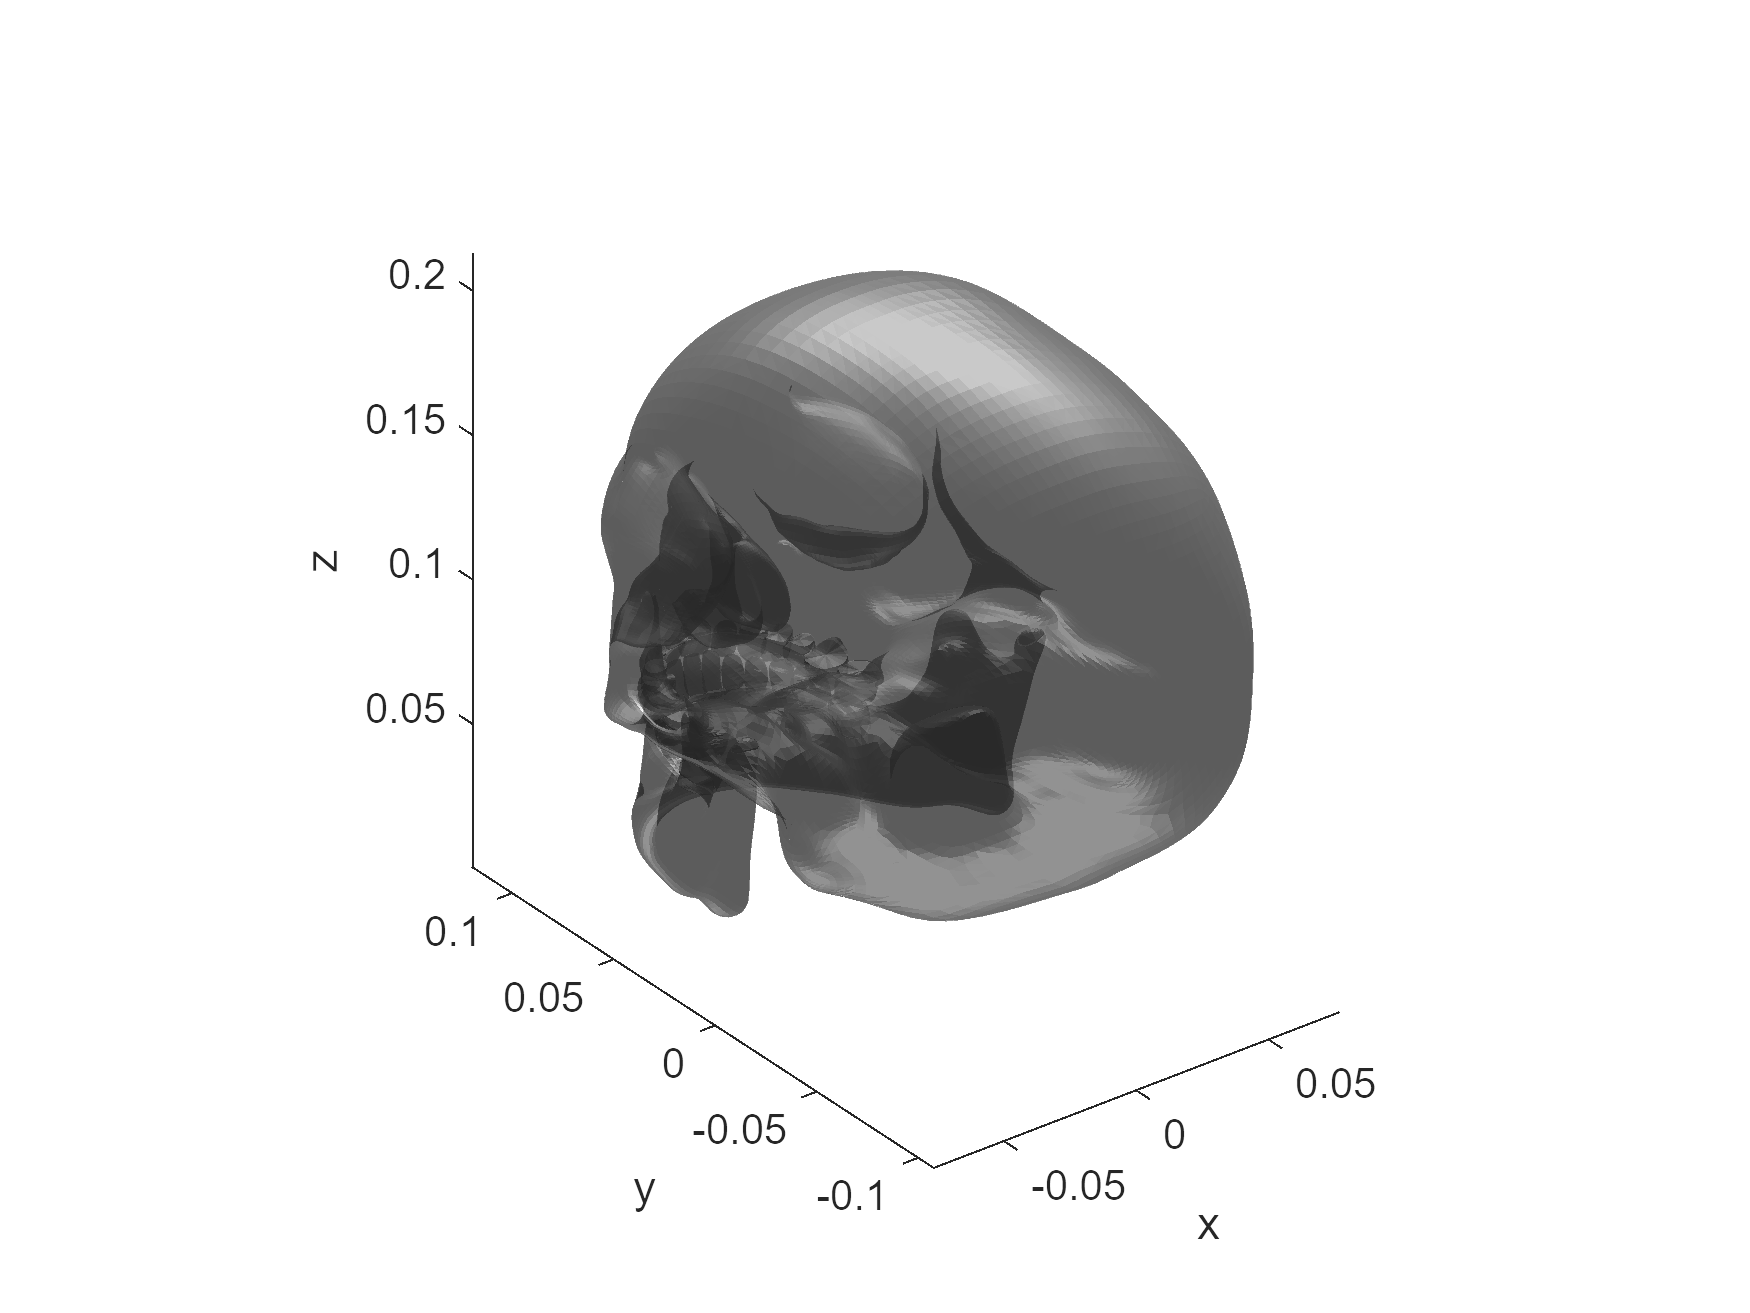

% patch('Vertices',v,'Faces',f,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.1)
axis equal
xyzlabel

### Fiducials wrt {I}

Use the Dicom images to place the fiducial relative to Image Reference Frame {I}.

See: 5_Skull_pose_estimation.mlx and use the skull to make the exercise.

**Expected results**

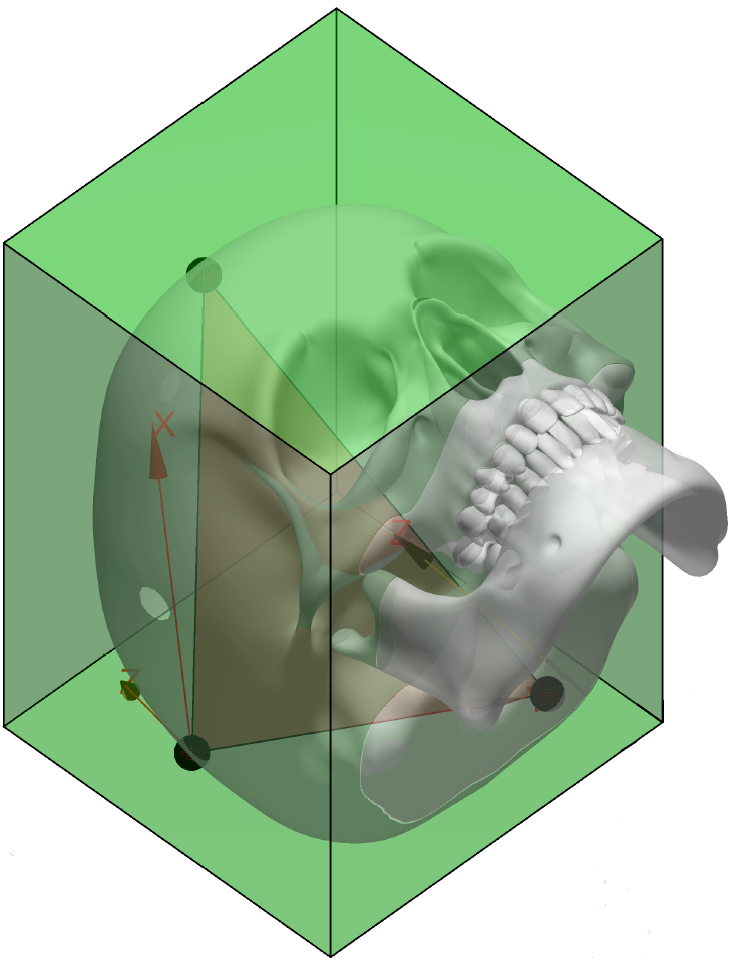

## put your code Here

pFid1 = [122, 61 , 131.6];
pFid2 = [185, 209 , 91];
pFid3 = [71, 212 , 44.8];

%MEDIDA CAJA DICOM
minXDic = 41;
maxXDic = 206;
minYDic = 27;
maxYDic = 234;
minZDic = 0;
maxZDic = 122 * 1.4;

minHeadDicom = [minXDic,minYDic,minZDic];
maxHeadDicom = [maxXDic,maxYDic,maxZDic];

pFid = [pFid1;pFid2;pFid3];
% PROP DICOM -> SKULL
minSkullZ = 0.072

minSkullZ = 0.0720

minSkull(3) = 0.072

minSkull =    -0.0765   -0.1077    0.0720


dicomToSkull = (maxSkull-minSkull) ./ (maxHeadDicom-minHeadDicom)

dicomToSkull =     0.0009    0.0011    0.0008


pFidS = pFid .* dicomToSkull

pFidS =     0.1131    0.0669    0.1084
    0.1715    0.2293    0.0749
    0.0658    0.2326    0.0369


maxDicomSkull = maxHeadDicom .* dicomToSkull;
minDicomSkull = minHeadDicom .* dicomToSkull;

maxDicomS2 = maxDicomSkull - (maxDicomSkull - maxSkull)

maxDicomS2 =     0.0765    0.1194    0.2127


minDicomS2 = minDicomSkull-(minDicomSkull - maxSkull)

minDicomS2 =     0.0765    0.1194    0.2127


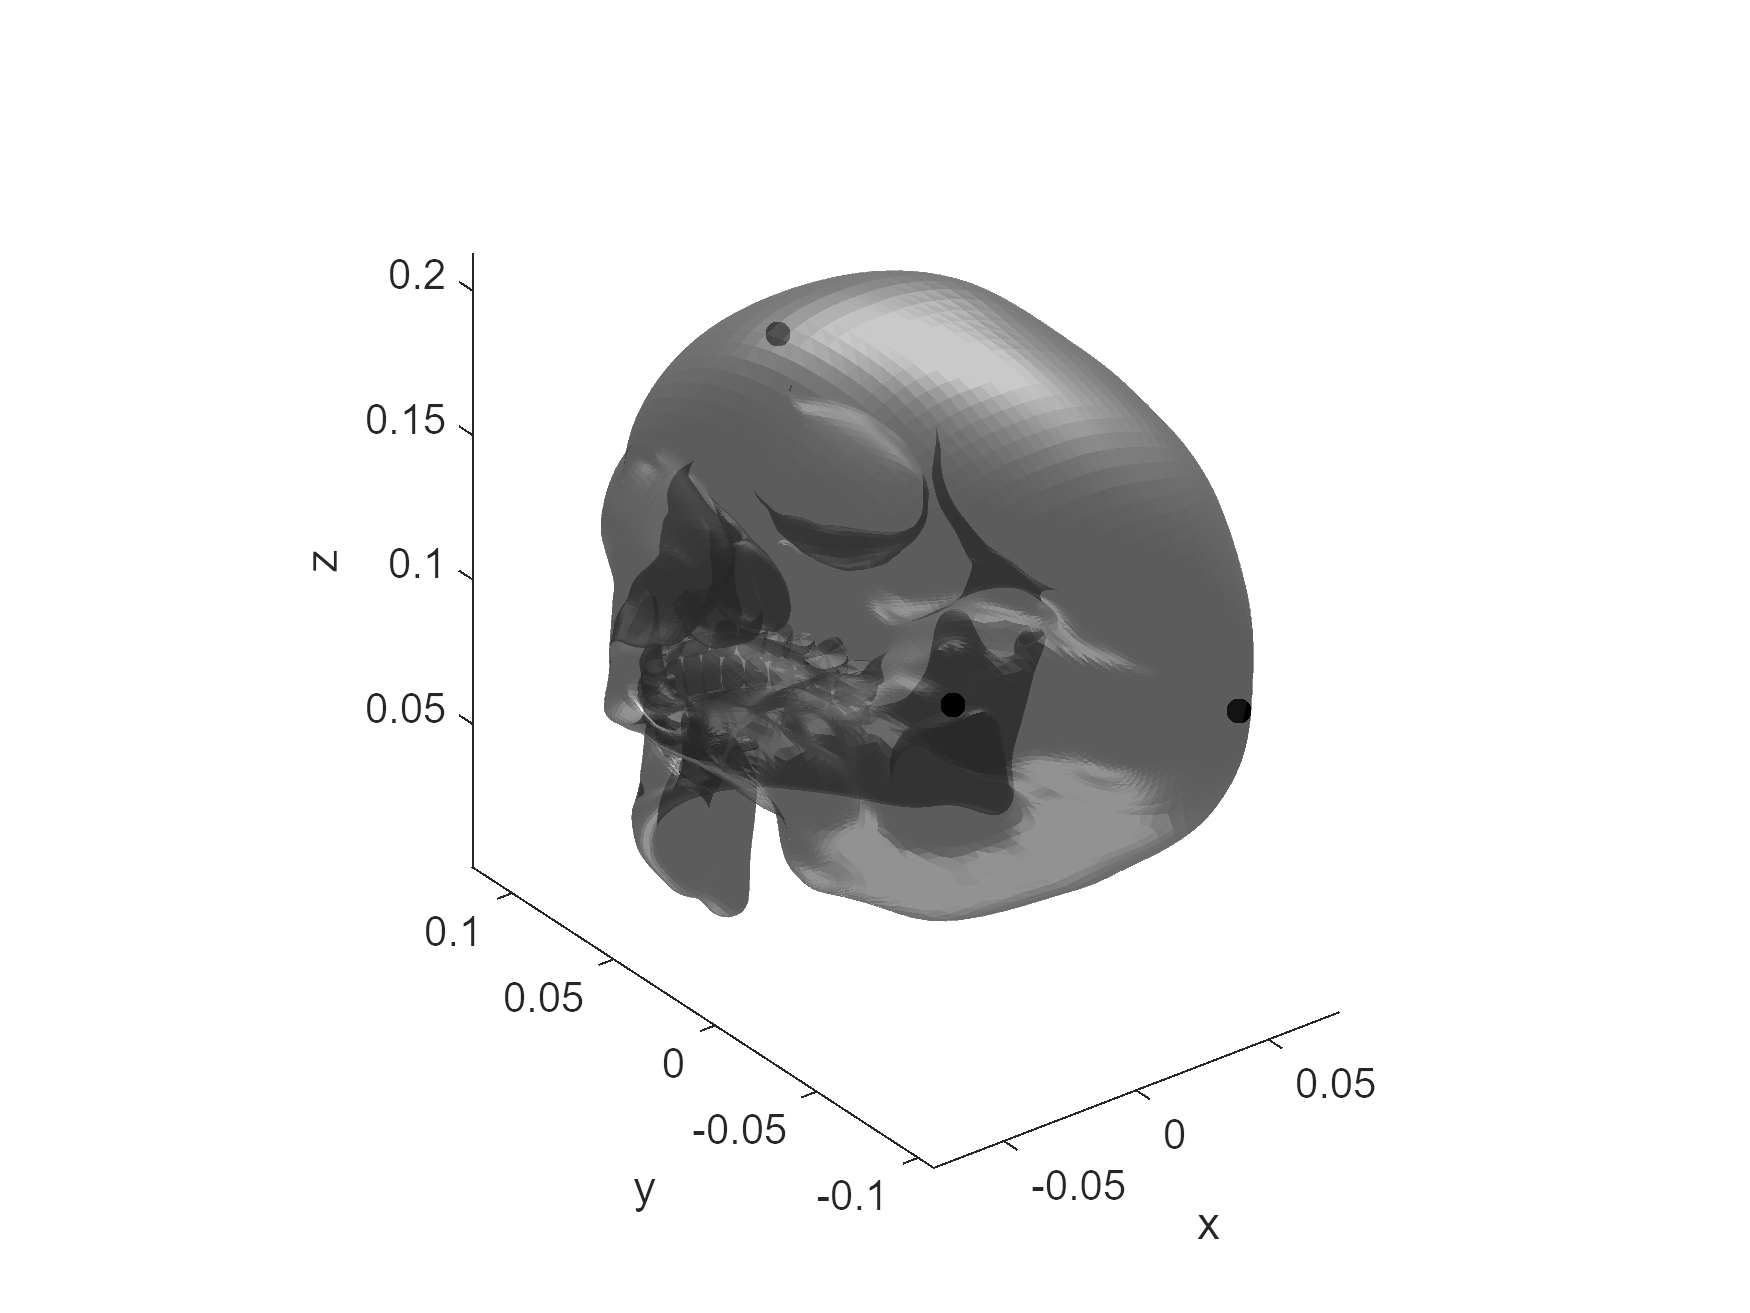


maxDicomSkullAux = minDicomSkull';
maxDicomSkullAux(4,:) = 1;
maxDicomSkullAux = trotz(pi) * maxDicomSkullAux;
maxDicomSkullAux = maxDicomSkullAux(1:3,:);
hold on
% scatter3(pFidS(1,1),pFidS(1,2),pFidS(1,3))
% scatter3(pFidS(2,1),pFidS(2,2),pFidS(2,3))
% scatter3(pFidS(3,1),pFidS(3,2),pFidS(3,3))
% scatter3(minDicomSkullAux(1),minDicomSkullAux(2),minDicomSkullAux(3))
% scatter3(minDicomS2(1),minDicomS2(2),minDicomS2(3))
% scatter3(maxDicomS2(1),maxDicomS2(2),maxDicomS2(3))
% scatter3(minSkull(1),minSkull(2),minSkull(3))
% scatter3(maxSkull(1),maxSkull(2),maxSkull(3))
% scatter3(maxDicomSkullAux(1),maxDicomSkullAux(2),maxDicomSkullAux(3))

T_D_S = trotz(pi)*transl(minSkull-minDicomSkull);

pFidS = pFidS';
pFidS(4,:) = 1;
pFidS1 = T_D_S  * pFidS;
pFidS1 = pFidS1(1:3,:)';
hold on
scatter3(pFidS1(1,1),pFidS1(1,2),pFidS1(1,3),'filled','MarkerFaceColor',[0 0 0])
scatter3(pFidS1(2,1),pFidS1(2,2),pFidS1(2,3),'filled','MarkerFaceColor',[0 0 0])
scatter3(pFidS1(3,1),pFidS1(3,2),pFidS1(3,3),'filled','MarkerFaceColor',[0 0 0])

### Tumor points wrt {I}

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

You can simplify the tumor information by defining the center of mass and estimate an equivalent diameter.

**Expected results**

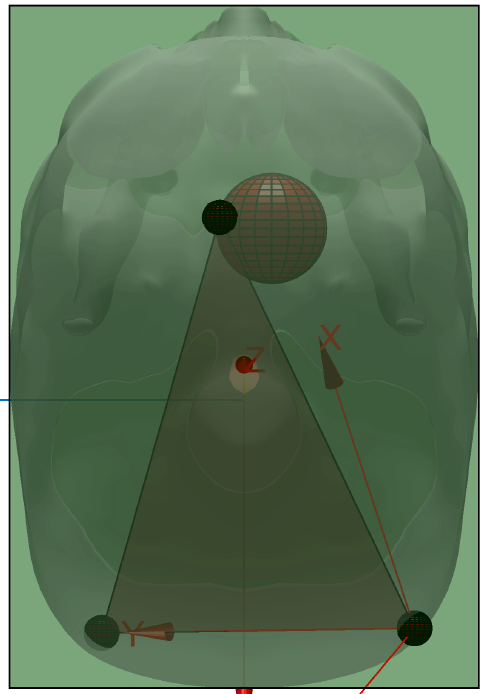

% TUMOR
tumorCenterDicom = [130 97.5 108]

tumorCenterDicom =   130.0000   97.5000  108.0000


tumorMaxZ = 90*1.4

tumorMaxZ = 126.0000

tumorMinZ = 64*1.4

tumorMinZ = 89.6000


tumorMaxX = 148

tumorMaxX = 148

tumorMinX = 113

tumorMinX = 113


tumorMaxY = 115

tumorMaxY = 115

tumorMinY = 80

tumorMinY = 80


difTZ = tumorMaxZ - tumorMinZ

difTZ = 36.4000

difTX = tumorMaxX - tumorMinX

difTX = 35

difTY = tumorMaxY - tumorMinY

difTY = 35


radioTumor = ((difTZ + difTY + difTX) / 3) / 2

radioTumor = 17.7333


hold on
% Make unit sphere
[xT,yT,zT] = sphere;
% Scale to desire radius.
radius = [radioTumor * dicomToSkull(1),radioTumor * dicomToSkull(1), radioTumor * dicomToSkull(1)];
xT = xT * radius(1);
yT = yT * radius(2);
zT = zT * radius(3);
% Translate sphere to new location.
tumorCenterSkull = tumorCenterDicom .* dicomToSkull

tumorCenterSkull =     0.1205    0.1070    0.0889


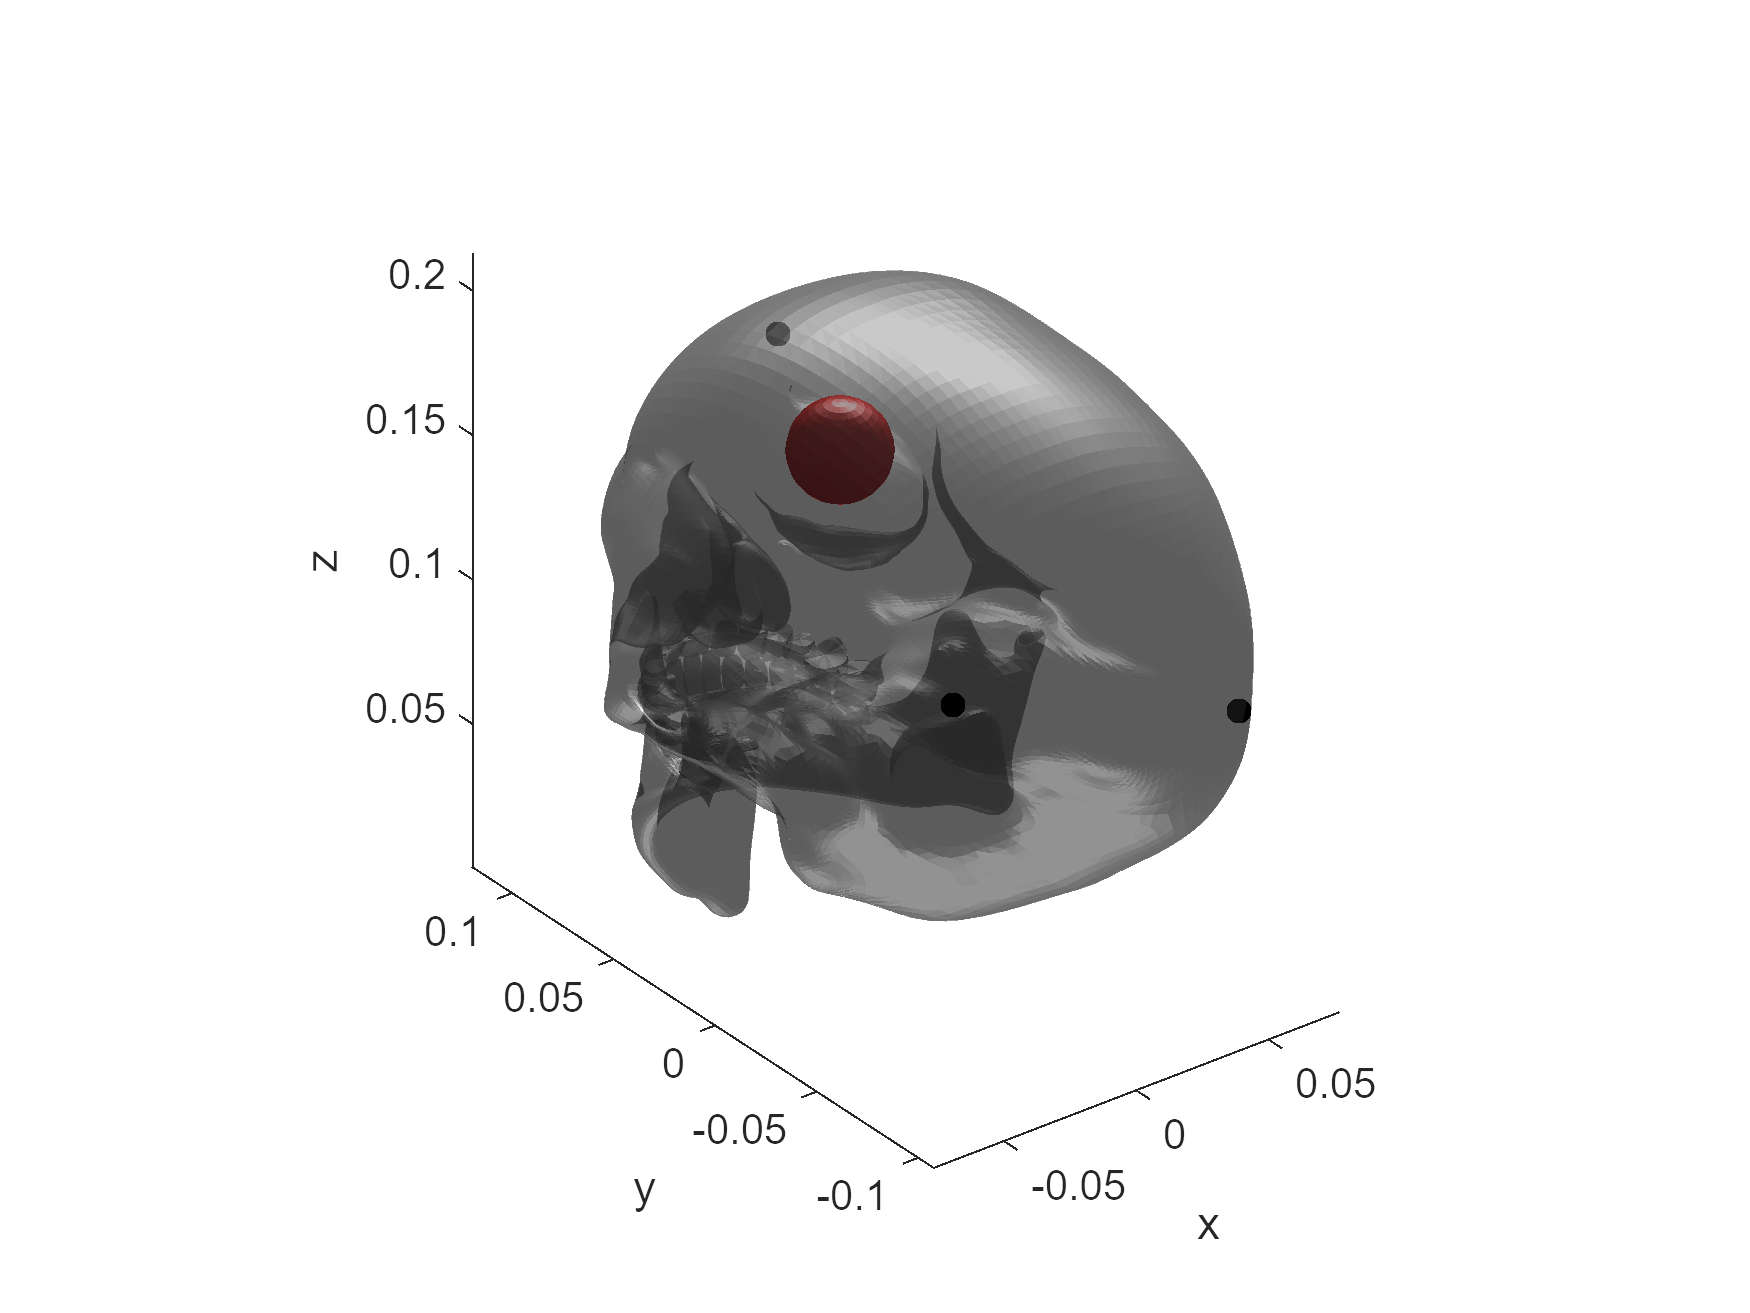

positionTum = tumorCenterSkull';
positionTum(4,:) = 1;
positionTum = T_D_S * positionTum;
positionTum = positionTum(1:3,:)';

offsetx = positionTum(1);
offsety = positionTum(2);
offsetz = positionTum(3);

surf(xT+offsetx,yT+offsety,zT+offsetz,'FaceColor','r','EdgeColor','none')
axis equal;
xyzlabel

### Fiducials and Tumor wrt Human Reference Frame

Place fiducial and tumor in the head of the human. You will have to re-do the containing box secction.

**Expected results**

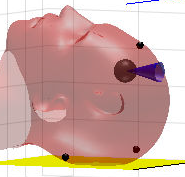

clf
hold on
xyzlabel
%TABLE
T_M_0 = transl(0)*trotx(0)*troty(0)*trotz(pi);

minXMesa = 0

minXMesa = 0

minYMesa = 0

minYMesa = 0

maxXMesa = 2

maxXMesa = 2

maxYMesa = 0.75

maxYMesa = 0.7500

minZMesa = 0.5

minZMesa = 0.5000

maxZMesa = 0.6

maxZMesa = 0.6000

vM = [minXMesa minYMesa minZMesa; minXMesa maxYMesa minZMesa; maxXMesa maxYMesa minZMesa; maxXMesa minYMesa minZMesa;minXMesa minYMesa maxZMesa; minXMesa maxYMesa maxZMesa; maxXMesa maxYMesa maxZMesa; maxXMesa minYMesa maxZMesa];
fM = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];
view(3)

vM2 = vM';
vM2(4,:) = 1;
vM2 = T_M_0 * vM2;
vM2 = vM2(1:3,:)';

patch('Faces',fM,'Vertices',vM2,'FaceColor',[0 0.5 0])

vP1 = vM - [0 0 0.5];
vP1 = vP1 .* [0.05 0.1333 5];

vP2 = vP1';
vP2(4,:) = 1;
vP2 = T_M_0 * vP2;
vP2 = vP2(1:3,:)';

patch('Faces',fM,'Vertices',vP2,'FaceColor',[0.1 0.1 0.1])

vP1 = vM - [0 0 0.5];
vP1 = vP1 .* [0.05 0.1333 5];
vP1 = vP1 + [1.9 0 0];

vP2 = vP1';
vP2(4,:) = 1;
vP2 = T_M_0 * vP2;
vP2 = vP2(1:3,:)';
patch('Faces',fM,'Vertices',vP2,'FaceColor',[0.1 0.1 0.1])

vP1 = vM - [0 0 0.5];
vP1 = vP1 .* [0.05 0.1333 5];
vP1 = vP1 + [0 0.65 0];

vP2 = vP1';
vP2(4,:) = 1;
vP2 = T_M_0 * vP2;
vP2 = vP2(1:3,:)';

patch('Faces',fM,'Vertices',vP2,'FaceColor',[0.1 0.1 0.1])

vP1 = vM - [0 0 0.5];
vP1 = vP1 .* [0.05 0.1333 5];
vP1 = vP1 + [1.9 0.65 0];

vP2 = vP1';
vP2(4,:) = 1;
vP2 = T_M_0 * vP2;
vP2 = vP2(1:3,:)';
patch('Faces',fM,'Vertices',vP2,'FaceColor',[0.1 0.1 0.1])

%HUMAN
load('F_V_HumanBody.mat')
T_C_M = T_M_0*transl(0.45,0.375,0.77)*trotz(-pi/2)*trotx(-pi/2);

Vh = Vh;
Vh(:,4) = 1;
Vh = T_C_M * Vh';

vH2 = Vh(1:3,:);
minCuerpo = min(vH2');
maxCuerpo = max(vH2');

vCH = [minCuerpo(1) minCuerpo(2) minCuerpo(3); minCuerpo(1) maxCuerpo(2) minCuerpo(3); maxCuerpo(1) maxCuerpo(2) minCuerpo(3); maxCuerpo(1) minCuerpo(2) minCuerpo(3);minCuerpo(1) minCuerpo(2) maxCuerpo(3); minCuerpo(1) maxCuerpo(2) maxCuerpo(3); maxCuerpo(1) maxCuerpo(2) maxCuerpo(3); maxCuerpo(1) minCuerpo(2) maxCuerpo(3)];
fCH = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];

% patch('Faces',fCH,'Vertices',vCH,'FaceColor',[1 0 0],'FaceAlpha',0.1)

patch('Vertices',Vh(1:3,:)','Faces',Fh,'FaceColor', [0.82 0.64 0.52], 'EdgeColor' , 'none', 'FaceAlpha', 0.6)

hold on;

%FIDUCIALS
view(3)
axis equal
light('Position',[3,3,3]);
% scatter3(pFidS1(1,1),pFidS1(1,2),pFidS1(1,3),'filled','MarkerFaceColor',[0 0 0])
% scatter3(pFidS1(2,1),pFidS1(2,2),pFidS1(2,3),'filled','MarkerFaceColor',[0 0 0])
% scatter3(pFidS1(3,1),pFidS1(3,2),pFidS1(3,3),'filled','MarkerFaceColor',[0 0 0])

%TUMOR
% surf(xT+offsetx,yT+offsety,zT+offsetz,'FaceColor','r','EdgeColor','none')

%CABEZA RESPECTO A CUERPO  Z->Y X->Z Y->X
minXCabeza = 2.1;
maxXCabeza = 2.24;
minYCabeza = 0.29;
maxYCabeza = 0.45;
minZCabeza = 0.66;
maxZCabeza = 0.86;
maxCabeza = [maxXCabeza maxYCabeza maxZCabeza];
minCabeza = [minXCabeza minYCabeza minZCabeza];

center2 = minCabeza + (maxCabeza-minCabeza) /2;
center = (maxCabeza-minCabeza) /2;

minC = min(Vh')

minC =    -2.2495   -0.8833    0.6088    1.0000



T_H_C = T_C_M*transl(0,0,1.73)*trotx(pi/2)*trotz(pi/2); %*T_C_M



minCabeza2 = -center;
maxCabeza2 = center;

minCabeza2 = minCabeza2';
minCabeza2(4,:) = 1;
minCabeza2 = T_H_C * minCabeza2;
minCabeza2 = minCabeza2(1:3,:)';

maxCabeza2 = maxCabeza2';
maxCabeza2(4,:) = 1;
maxCabeza2 = T_H_C * maxCabeza2;
maxCabeza2 = maxCabeza2(1:3,:)';

vCabC = [minCabeza2(1) minCabeza2(2) minCabeza2(3); minCabeza2(1) maxCabeza2(2) minCabeza2(3); maxCabeza2(1) maxCabeza2(2) minCabeza2(3); maxCabeza2(1) minCabeza2(2) minCabeza2(3);minCabeza2(1) minCabeza2(2) maxCabeza2(3); minCabeza2(1) maxCabeza2(2) maxCabeza2(3); maxCabeza2(1) maxCabeza2(2) maxCabeza2(3); maxCabeza2(1) minCabeza2(2) maxCabeza2(3)];
fCabC = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];
% patch('Faces',fCabC,'Vertices',vCabC,'FaceColor',[1 1 0],'FaceAlpha',0.4)


% FIDUCIALS & TUMOR
pFidU = pFidS1;

propSkullUn = [1,1,1.4];
centerSkull = (minSkull + maxSkull) / 2

centerSkull =     0.0000    0.0059    0.1423


centerSkull = centerSkull .* propSkullUn;

T_F_C = T_C_M*transl(0,0,1.72-centerSkull(3))*trotz(pi); %*transl(minXCabeza-minC(1)+center(1),0,0)*transl(-centerSkull)*trotz(pi);  transl(0,0,minC(3)-center(3))*trotz(pi)*


pFidU = pFidU .* propSkullUn

pFidU =     0.0014    0.0704    0.2525
   -0.0570   -0.0920    0.2057
    0.0487   -0.0953    0.1524


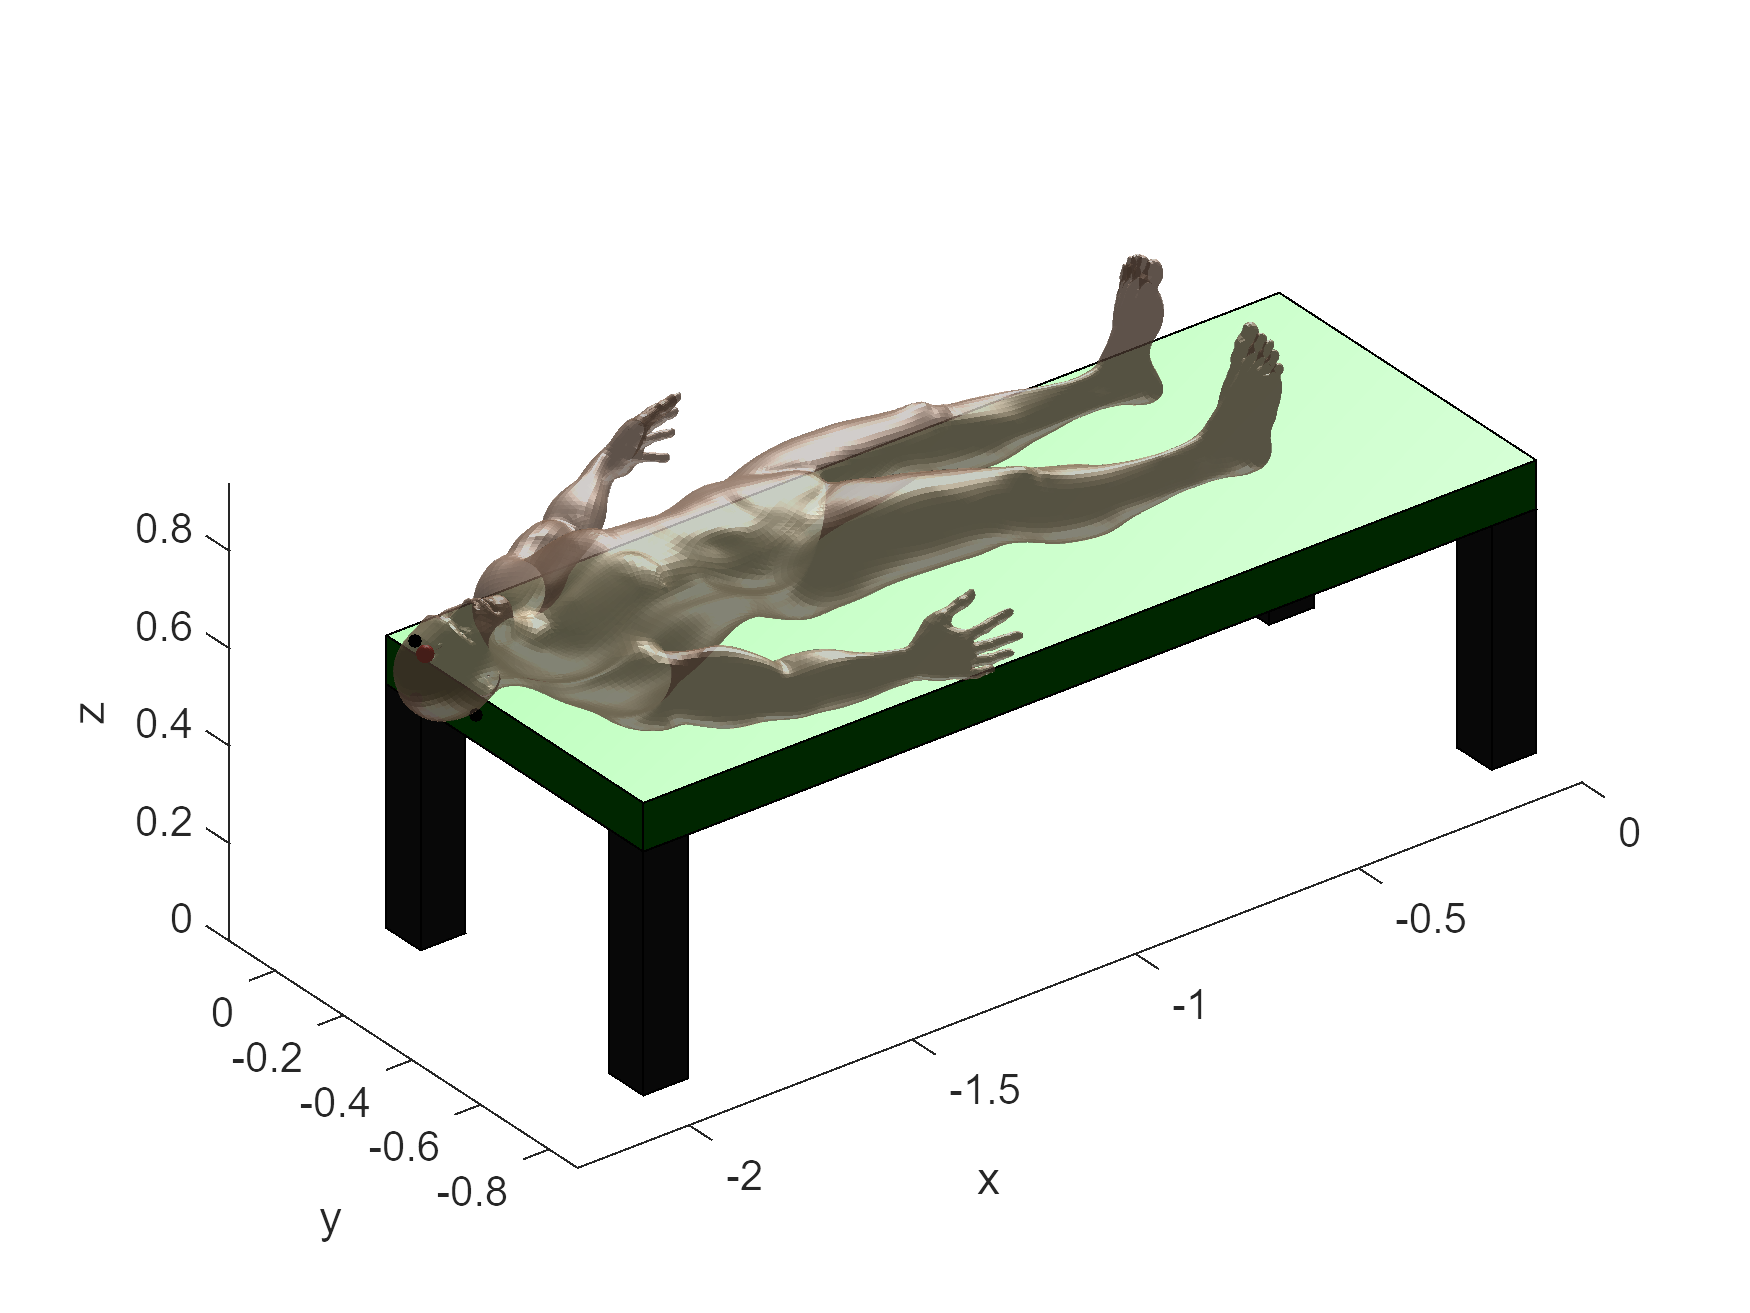


pFidU = pFidU';
pFidU(4,:) = 1;
pFidU = T_F_C * pFidU;
pFidU = pFidU(1:3,:)';

scatter3(pFidU(1,1),pFidU(1,2),pFidU(1,3),10,'filled','MarkerFaceColor',[0 0 0])
scatter3(pFidU(2,1),pFidU(2,2),pFidU(2,3),10,'filled','MarkerFaceColor',[0 0 0])
scatter3(pFidU(3,1),pFidU(3,2),pFidU(3,3),10,'filled','MarkerFaceColor',[0 0 0])

positionTumUn = positionTum .* propSkullUn;
positionTumUn = positionTumUn';
positionTumUn(4,:) = 1;
positionTumUn = T_F_C * positionTumUn;
positionTumUn = positionTumUn(1:3,:)';

offsetx = positionTumUn(1);
offsety = positionTumUn(2);
offsetz = positionTumUn(3);

surf(xT+offsetx,yT+offsety,zT+offsetz,'FaceColor','r','EdgeColor','none')

## *First approach (10%)  *

*Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

### Robot manipulator

Consider  the best position of manipulator to be nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560. Use p560.teach to play.

Use: p560.base & p560.tool to locate the Puma and add the tools.

**Expected results**

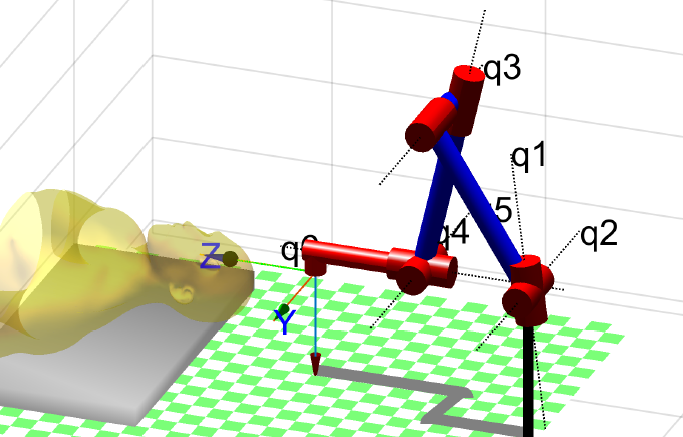

mdl_puma560;
hold on;
p560.tool.T

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


% p560.plot(qr,'zoom',1.5)
T_R_M=T_C_M*transl(0,0.1,2.35)*trotx(pi)*trotz(pi/2);
p560.base=T_R_M

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (-2.8, -0.375, 0.67), RPY/xyz = (0, 90, 180) deg    
 


hold on;
p560.tool = trotz(pi/2)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (-2.8, -0.375, 0.67), RPY/xyz = (0, 90, 180) deg    
tool:    t = (0, 0, 0), RPY/xyz = (90, 0, 0) deg                 
 


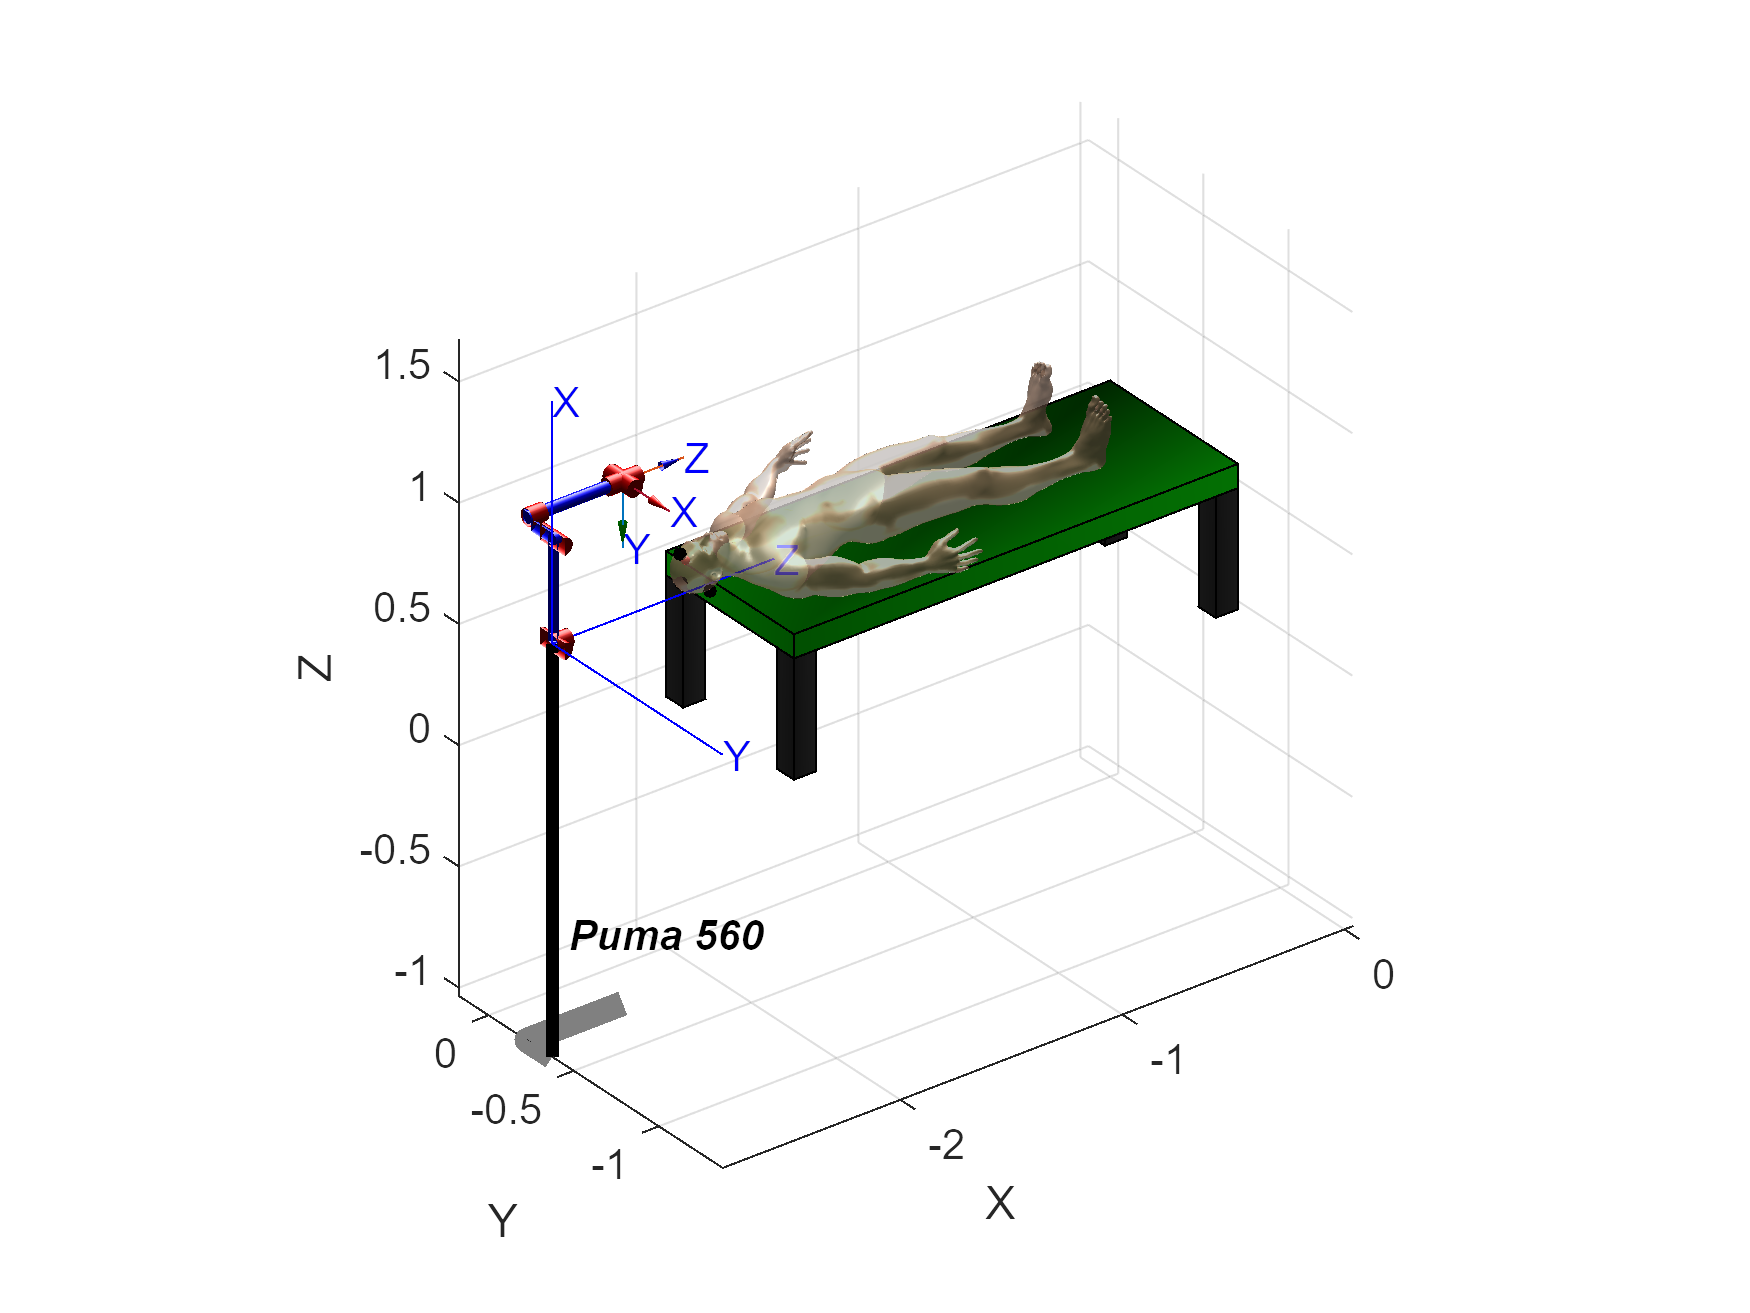

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.




p560.base.plot(qz,'zoom',1.5,'notiles');
p560.plot(qz,'zoom',1.5,'notiles');

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {Tt} Table tool

- {EE} End Efector

- others

- ...

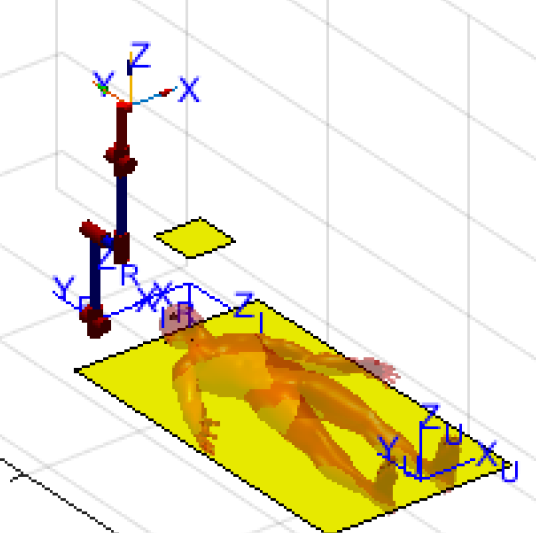

## put your code Here

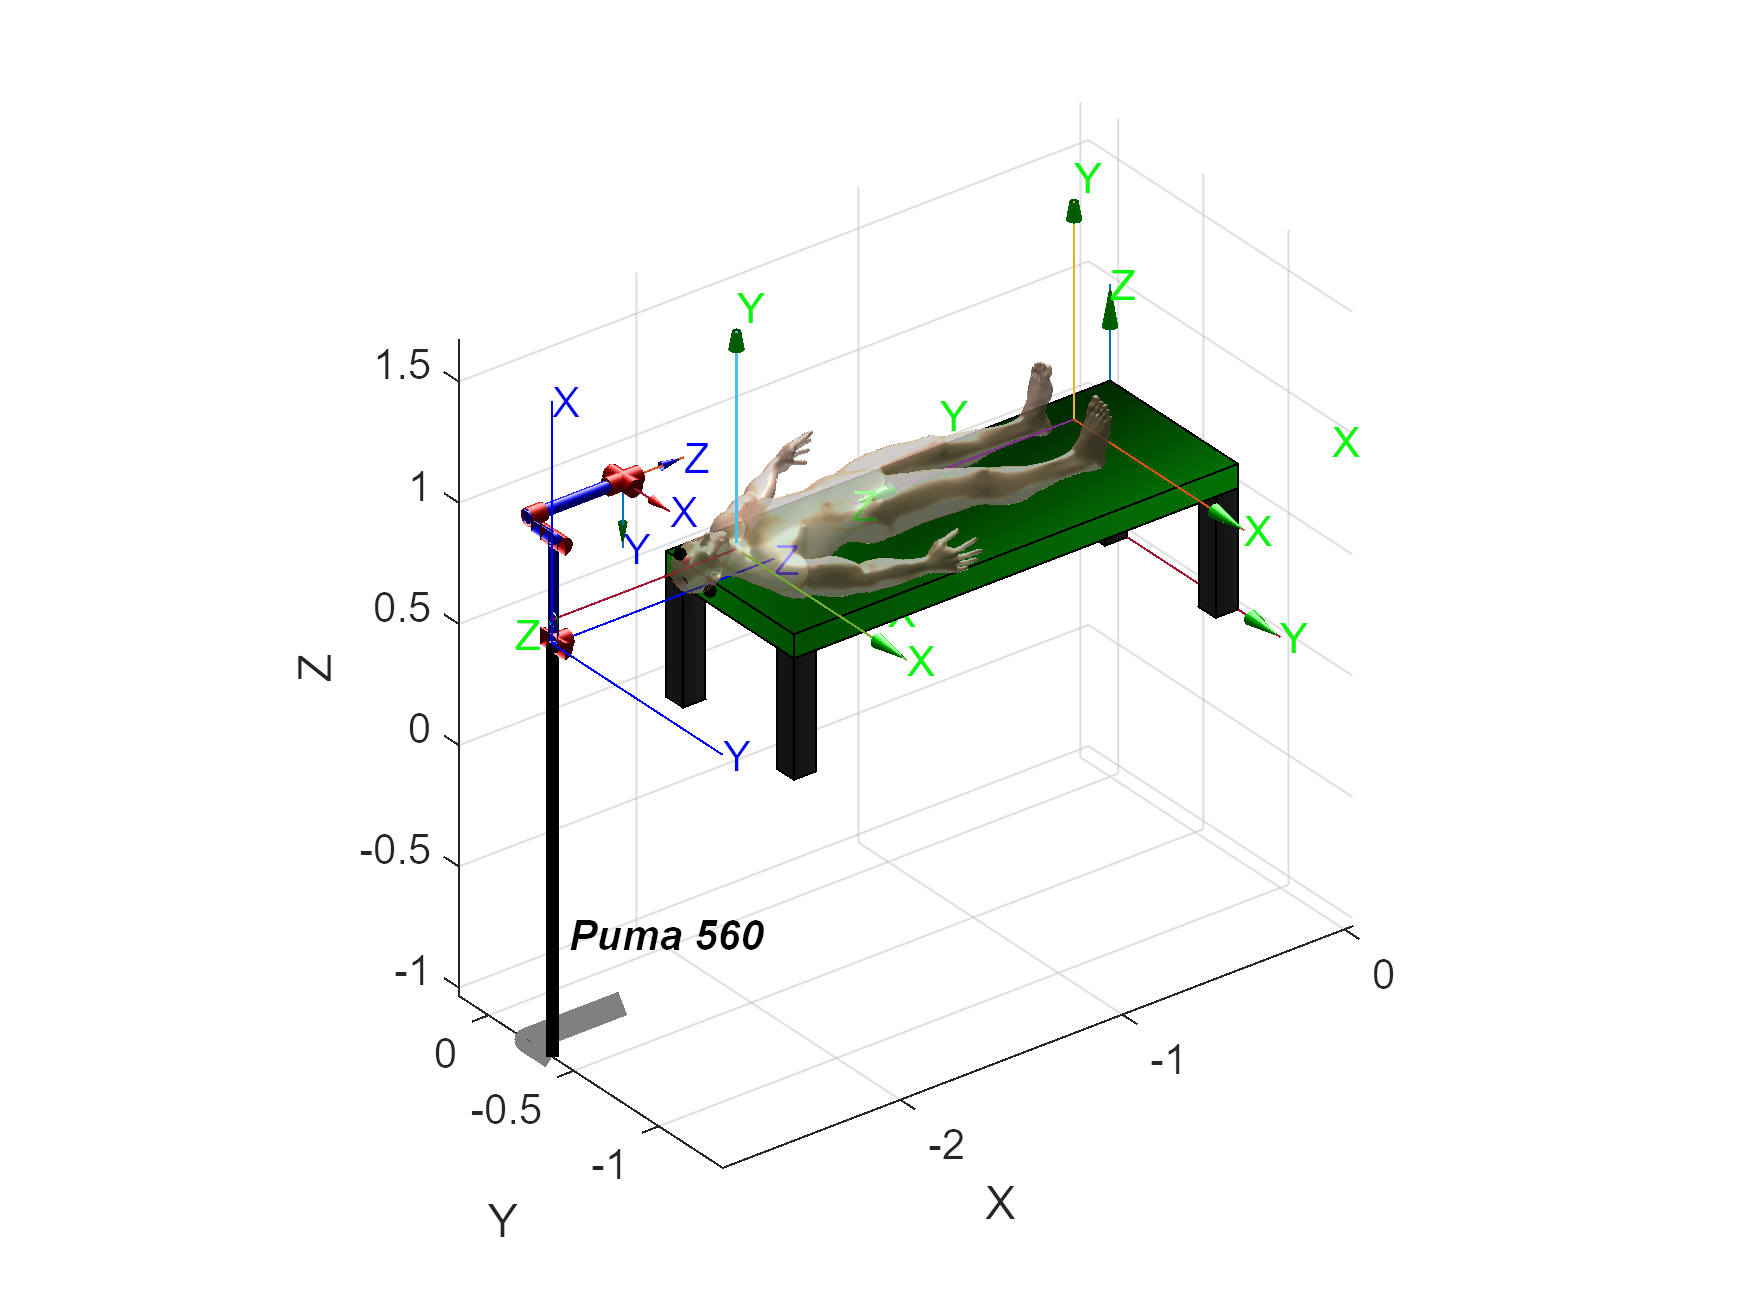

hold on;
T_0 = transl(0);
trplot(T_0,'framelabel','B','color','g','arrow','width',1);

T_M_0;
trplot(T_M_0,'framelabel','B','color','g','arrow','width',1);

T_C_0 = T_C_M * T_M_0;
trplot(T_C_0,'framelabel','B','color','g','arrow','width',1);

T_F_0 = T_F_C * T_M_0;
trplot(T_F_C,'framelabel','B','color','g','arrow','width',1);

### Transformations

Enumerate the transformation you will need.

### Tumor points in Robot Frame.

Remember the Transform compound exercise

## put your code Here

T_F_R = T_F_C * T_C_M / T_R_M
pFidR = pFidU';
pFidR(4,:) = 1;
pFidR = T_F_R * pFidR;
pFidR = pFidR(1:3,:)';

## *Second approach: ( 25%)*

Modify your code  to repeat the exercise if  the table with the patient is given as happend in the Rosa video.

To know the head relative pose with respect to the Puma Robot ...

*See:  **‘4_Sckeching_Key_ideas_students.mlx’ , ‘5_Skull_pose estimation.mlx’ for inspiration and Second_approach_SPM.pdf*

open('3_Second_approach_Patient_pose.fig')

T_F_R =          0   -1.0000         0   -3.1157
    1.0000         0         0    2.8750
         0         0    1.0000   -0.2750
         0         0         0    1.0000


## Surgery (55%)

### Biospy

Prepare a script that perform a biopsy. Zoom in the scene and record a video with the best view.

Use a tool that has the following Transformation: transl(0.05 0 0.25)

Let us see the 'trail' option of plot to visualize the trajectory.

%% put your code Here

### Trepanation

Prepare a script that perform trepanation. Zoom in the scene and record a video with the best view.

Use a tool that has the following Transformation: transl(0 0 0.2)

Let us see the 'trail' option of plot to visualize the trajectory. Place a 45º cone on top of the trepanation to better understand. See: 6_Plot_Box_Cone.mlx. You will have to scale it. Play with transparency.

%% put your code Here

### Tumor burning

Prepare a script that perform tumor burning with the laser.  Zoom in the scene and record a video with the best view.

You ought to think in an algorithm, that in order, fill up the tumor's  equivalent sphere with small burning spheres of 4m diameter.

Use a tool that has the following Transformation: transl(0 0 0.2)

%% put your code Here